addpath('C:\Users\anapa\Documents\MATLAB\ppgeb_masters')

close all;
clear all;

%re-read lib
try
    unloadlibrary thinkgear
catch 
    warning('biblioteca ainda nao carregada')
end 
loadlibrary('thinkgear.dll');

%esperar conexão ser estabelecida no MATLAB
%% Generate path to GP3 subfolders
[mainDir,~,~] = fileparts(mfilename('fullpath'));
addpath(genpath(mainDir));

%% Set-up Matlab to GP3 session1 socket
session1_client = ConnectToGP3;

%% connect to mindwave
portnum1 =      4;      %COM port#
comPortName1 =  sprintf('\\\\.\\COM%d', portnum1);

TG_BAUD_115200 =      115200; 
TG_STREAM_PACKETS =       0;
TG_DATA_RAW =             4;

connectionId1 = calllib('thinkgear', 'TG_GetNewConnectionId');
if ( connectionId1 < 0 )
    error ('ERROR: TG_GetNewConnectionId() returned %d.\n', connectionId1)
end

%set/open stream (raw bytes) log file for connection
errCode = calllib('thinkgear', 'TG_SetStreamLog', connectionId1, 'streamLog.txt' )

errCode = 0

if( errCode < 0 )
    error( 'ERROR: TG_SetStreamLog() returned %d.\n', errCode )
end

%set/open data (thinkgear values) log file for connection
errCode = calllib('thinkgear', 'TG_SetDataLog', connectionId1, 'dataLog.txt' );
if( errCode < 0 )
    error( 'ERROR: TG_SetDataLog() returned %d.\n', errCode );
end


%errCode = calllib('thinkgear', 'TG_Connect',  connectionId1,comPortName1,TG_BAUD_57600,TG_STREAM_PACKETS);
errCode = calllib('thinkgear', 'TG_Connect',  connectionId1,comPortName1,TG_BAUD_115200,TG_STREAM_PACKETS);
if ( errCode < 0 )
    error( 'ERROR: TG_Connect() returned %d.\n', errCode);
end

ERROR: TG_Connect() returned -2.

%to save data from all columns
seg = 20
linhas = seg * 512
data = ones(linhas, 6);

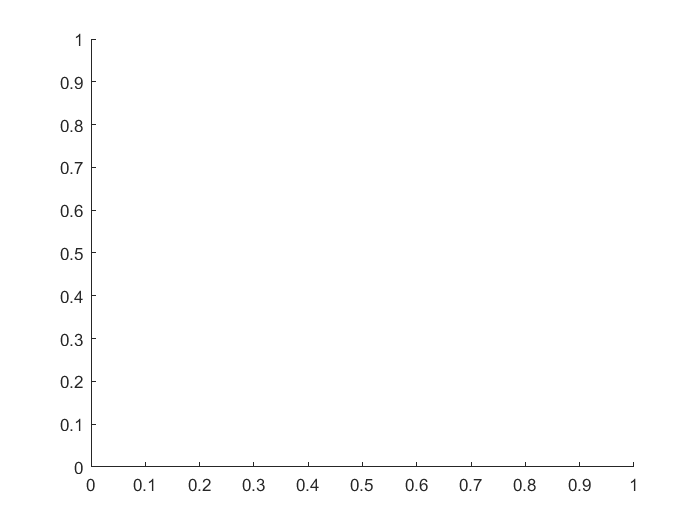

Error using sprintf
Unable to convert 'matlab.graphics.primitive.Text' value to 'char' or 'string'.

Unrecognized function or variable 'filename'.

%% Spawn a second Matlab session2 that records GP3 data to output file
outputFileName = 'piscada2.txt';
ExecuteRecordGP3Data(session1_client,outputFileName);


j = 0;
i = 0;
while (i < 51200)   %loop for 60 seconds
    if (calllib('thinkgear','TG_ReadPackets',connectionId1,1) == 1)   %if a packet was read...
        
            if (calllib('thinkgear','TG_GetValueStatus',connectionId1,TG_DATA_RAW) ~= 0)   %if RAW has been updated 
                j = j + 1;
                i = i + 1;
                data(j) = calllib('thinkgear','TG_GetValue',connectionId1,TG_DATA_RAW);
                total(i) = calllib('thinkgear','TG_GetValue',connectionId1,TG_DATA_RAW);
                SendMsgToGP3(session1_client, num2str(calllib('thinkgear','TG_GetValue',connectionId1,TG_DATA_RAW)));
            end
    end
    
    
    if (j == 256)
        modPlotRAW(data);            %plot the data, update every .5 seconds (256 points)
        j = 0;
    end
    
end

raw = total; %return value of data

calllib('thinkgear', 'TG_FreeConnection', connectionId1 );